# **4.2.1 ****for-end**`语句`

**for-end**`语句（简称`**for**`循环）用于事先已知循环次数的情形``，其语法如下：`

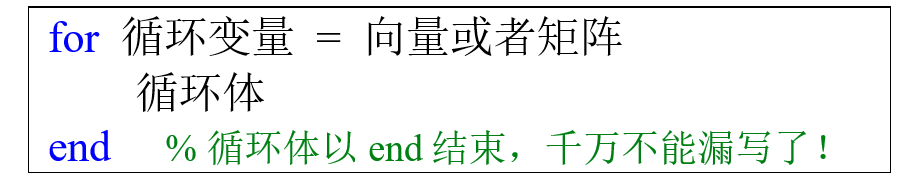

`在该语法中，循环变量是用于迭代的变量名，它会在每次循环迭代中从向量或矩阵中取出一列的值。数值向量或者矩阵则表示了循环变量可以取值的范围，通常根据实际需要事先给定。一旦循环变量遍历完数值向量或者矩阵中的所有值，循环就会结束。`

x = 1:5;
for ii = x
    ii
end

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

for ii = [3;5;9;8]
    ii
end

ii =      3
     5
     9
     8


x = [1 5 8;
    3 6 9;
    4 7 2;
    6 5 3];
for ii = x
    ii
end

ii =      1
     3
     4
     6


ii =      5
     6
     7
     5


ii =      8
     9
     2
     3


# `断点调试功能（非常重要！！！）`

`（`1`）不使用`sum`函数，计算行向量`x`中所有元素的和。`

x = [5 8 9 1 4 3 7]

x =      5     8     9     1     4     3     7


s = 0;  % 初始化最后的求和结果为0
for ii = x
    s = s + ii;
end
disp(s)

    37



在这个示例中，for 循环遍历了向量 x 中的每个元素，将它们逐个加到变量 s 中，最终得到了所有元素的和。

sum(x) == s

ans = logical
   1


`思考：如果`x`是一个列向量，左侧的代码输出的`s`是什么，应该如何修改代码？`

x = [1;2;3];
s = 0;  % 初始化最终的求和结果为0
for ii = x
    s = s + ii;
end
disp(s)

     1
     2
     3



修改代码：

x = [1;2;3]

x =      1
     2
     3


% if size(x,2) == 1
%     xx = x';
% else
%     xx = x;
% end
% x = [1 2 3]
xx = (x(:))'  % xx = transpose(x(:));

xx =      1     2     3


s = 0;  % 初始化最终的求和结果为0
for ii = xx
    s = s + ii;
end
disp(s)

     6



`（`2`）计算当`n`等于`100`时，下面式子的结果`:


$$y\left( n \right) \,\,=\,\,1+\frac{1}{2^2}+\frac{1}{3^2}+\cdots +\frac{1}{n^2}$$


写成求和形式：$y\left( n \right) \,\,=\sum_{k=1}^n{\frac{1}{k^2}}$

n = 100;  % 设置n的值
y = 0;    % 初始化y的值为0
for k = 1:n
    % 计算每一项并累加到y中
    y = y + 1 / (k^2);
end
disp(y)

    1.6350



在这个示例中，for 循环从 1 到 n 遍历每个整数 k，并计算每一项 1 / (k^2)，然后将它们累加到变量 y 中。最终，y 的值将是整个表达式的结果。

使用上一章的知识点，如何通过一行代码直接计算y的值？

y = sum(1./(1:100).^2)

y = 1.6350

`（`3`）``计算当`n`从`1`一直取到`100`时，上一小问式子`$y\left( n \right) \,\,=\,\,1+\frac{1}{2^2}+\frac{1}{3^2}+\cdots +\frac{1}{n^2}$`的计算结果，`

`并将计算结果保存到一个长度为`100`的行向量`S`中`

`（`S`中第`i`个元素表示`y(i)`的结果）。`

S = zeros(1, 100);
for n = 1:100
    y = 0;    % 初始化y的值为0
    for k = 1:n
        y = y + 1 / (k^2);
    end
    S(n) = y;
end
disp(S)

    1.0000    1.2500    1.3611    1.4236    1.4636    1.4914    1.5118    1.5274    1.5398    1.5498    1.5580    1.5650    1.5709    1.5760    1.5804    1.5843    1.5878    1.5909    1.5937    1.5962    1.5984    1.6005    1.6024    1.6041    1.6057    1.6072    1.6086    1.6098    1.6110    1.6122    1.6132    1.6142    1.6151    1.6160    1.6168    1.6175    1.6183    1.6190    1.6196    1.6202    1.6208    1.6214    1.6219    1.6225    1.6230    1.6234    1.6239    1.6243    1.6247    1.6251    1.6255    1.6259    1.6262    1.6266    1.6269    1.6272    1.6275    1.6278    1.6281    1.6284    1.6287    1.6289    1.6292    1.6294    1.6297    1.6299    1.6301    1.6303    1.6305    1.6307    1.6309    1.6311    1.6313    1.6315    1.6317    1.6319    1.6320    1.6322    1.6324    1.6325    1.6327    1.6328    1.6330    1.6331    1.6332    1.6334    1.6335    1.6336    1.6338    1.6339    1.6340    1.6341    1.6342    1.6344    1.6345    1.6346    1.6347    1.6348    1.6349    1.6350

`这里使用了循环的嵌套，上一问的代码可用来求出任意一个具体的`n`对应的`y`。`

`因此，这一问我们只需要使用循环让`n`从`1`遍历到`100`，并将每次的计算结果保存到向量`S`中。`

`请大家思考：`

`（`1`）`y = 0;`这行代码能否放在循环的外面？`

 `（`2`）能否优化代码，使得通过一次循环就得到`S`。`

`这两个问题留作本章最后的课后习题``。`

`（`4`）计算从公元`1`年到公元`9999`年间，有多少个闰年。闰年的判读条件是年份能够被`4`整除，但不能被`100`整除，或者年份能够被`400`整除。`

% 初始化闰年计数器
leap_year_count = 0;
% 循环遍历从公元1年到公元9999年的每一年
for year = 1:9999
    % 检查是否为闰年的条件
    if (mod(year, 4) == 0 && mod(year, 100) ~= 0) || (mod(year, 400) == 0)
        % 如果是闰年，增加计数器
        leap_year_count = leap_year_count + 1;
    end
end
disp(leap_year_count)

        2424



`（`5`）一个三位正整数各位数字的立方和等于该数本身则称该数为水仙花数，`

`例如：`1^3 + 5^3+ 3^3 = 153`，则`153`是水仙花数。请你找出所有的水仙花数并将其保存到向量`S`中。`

% 初始化存储水仙花数的向量S为空
S = [];
% 循环遍历所有的三位整数
for num = 100:999
    % 拆解数字
    digit1 = floor(num / 100);     % 百位
    digit2 = floor(mod(num, 100) / 10);  % 十位
    digit3 = mod(num, 10);          % 个位
    % 检查是否为水仙花数的条件
    if num == digit1^3 + digit2^3 + digit3^3
        S = [S, num];  % 若是水仙花数，则添加到向量S中
    end
end
% 显示所有的水仙花数
disp(S)

   153   370   371   407



拓展：使用字符向量拆分数字

n = 896

n = 896

% num2str(n)
str2num((num2str(n))')

ans =      8
     9
     6


% 初始化存储水仙花数的向量S为空
S = [];
% 循环遍历所有的三位整数
for num = 100:999
    % 拆解数字
    tmp = str2num((num2str(num))');
    % 检查是否为水仙花数的条件
    if num == tmp(1)^3 + tmp(2)^3 + tmp(3)^3
        S = [S, num];  % 若是水仙花数，则添加到向量S中
    end
end
% 显示所有的水仙花数
disp(S)

   153   370   371   407



`（`6`）斐波那契数列的递推公式为`$\left\{ \begin{array}{l}
	F\left( 1 \right) =1,F\left( 2 \right) =1\\
	F\left( n \right) =F\left( n-1 \right) +F\left( n-2 \right) , n\,\,\ge 3\\
\end{array} \right. $, `求`$F\left( 30 \right) $.

n = 30;
F = ones(1,n);   % 初始化用来保存中间计算结果的向量全为1
for k = 3:n
    F(k) = F(k-1) + F(k-2);
end
Fn = F(n)

Fn = 832040

% 832040

`（`7`）生成一个`5`行`8`列的矩阵，矩阵中每个元素都是在区间`[1, 10]`上取值的随机整数。接下来请循环每一列，若发现同一列的五个元素各不相同，则保留该列；若该列中有重复的元素则删除该列。`

你能不使用循环语句求解这个问题吗？

% 生成随机整数矩阵
matrix = randi([1, 10], 5, 8);
% 输出生成的随机整数矩阵
disp(matrix)

     1     6     2     9     2     1    10     5
     9     1     6     7     5     2     9     8
    10     1     8     2     6     5     1     9
     5     2     6     9    10     5     1     5
     5     3     8     5    10     7     1     4



% 初始化新矩阵，用于存储五个元素各不相同的列
new_matrix = [];
% 循环遍历每一列
for column = matrix
    % % 使用unique函数取当前列的唯一值
    % unique_column = unique(column);
    % % 若取完唯一值后还是5个元素，则添加到新矩阵中
    % if length(unique_column) == 5
    %     new_matrix = [new_matrix, column];
    % end
    [~,f] = mode(column);
    if f == 1
        new_matrix = [new_matrix, column];
    end

end
disp(new_matrix)  % 显示新矩阵的结果

你能不使用循环语句求解这个问题吗？

matrix

matrix =      1     6     2     9     2     1    10     5
     9     1     6     7     5     2     9     8
    10     1     8     2     6     5     1     9
     5     2     6     9    10     5     1     5
     5     3     8     5    10     7     1     4


sort(matrix)

ans =      1     1     2     2     2     1     1     4
     5     1     6     5     5     2     1     5
     5     2     6     7     6     5     1     5
     9     3     8     9    10     5     9     8
    10     6     8     9    10     7    10     9


diff(sort(matrix))

ans =      4     0     4     3     3     1     0     1
     0     1     0     2     1     3     0     0
     4     1     2     2     4     0     8     3
     1     3     0     0     0     2     1     1


all(diff(sort(matrix)))

ans = 1×8 logical 数组
   0   0   0   0   0   0   0   0


matrix(:,all(diff(sort(matrix))))


ans =

  空的 5×0 double 矩阵



`在使用`**for**`循环时，需要注意以下事项：`

（1）若for语句后面的向量或者矩阵为空，则循环一次也不会被执行。

for ii = 2:1
    x = 10;
    disp(x)
end
% MATLAB什么都不会输出

for ii = []
    x = 10;
    disp(x)
end
% MATLAB什么都不会输出


`（`2`）`for`语句后面的向量或者矩阵只会在循环开始时使用一次，向量或者矩阵元素一旦确定将不会再改变。即使你在循环体中改变向量或者矩阵的值，循环变量的值也不改变。`

x = 1:4;
for ii = x
    x = [0 0 0 0];
    disp(ii)
end

     1

     2

     3

     4



disp(x)

     0     0     0     0



`（`3`）可以在循环体中修改循环变量的值，但当程序执行流程再次回到循环开始时，循环变量会自动恢复成向量或者矩阵的下一列元素。`

for ii = 1:3
    disp(ii)
    ii = 10;
    disp(ii)
end

     1



    10



     2



    10



     3



    10



配套的讲解视频可在b站免费观看：

《MATLAB教程新手入门篇（数学建模清风主讲，适合零基础同学观看）》

[https://www.bilibili.com/video/BV1dN4y1Q7Kt/](https://www.bilibili.com/video/BV1dN4y1Q7Kt/)